# Lab 8 by Cole Bardin 		Section 61

## Water Clocks: The Polyvascular Clepsydra and the Laplace Transform

## Questions 1-2

clc, clear, close all

% Question 1
syms s t Y
y0 = 1 % initial condition

y0 = 1

Y1 = s*Y - y0 % transform of the derivative

$$Y1 = Y\,s-1$$


LTofDE = Y1 == -1*Y

$$LTofDE = Y\,s-1=-Y$$

Sol = solve(LTofDE, Y)

$$Sol = \frac{1}{s+1}$$

Y = matlabFunction(Sol); Y(s);
Y = partfrac(Y(s)) % express solution in partial fraction form

$$Y = \frac{1}{s+1}$$

sol = ilaplace(Sol,s,t);
y = matlabFunction(sol); y(t)

$$ans = {\mathrm{e}}^{-t}$$

% Question 2
H = matlabFunction(1-y(t)); H(1)

ans = 0.6321

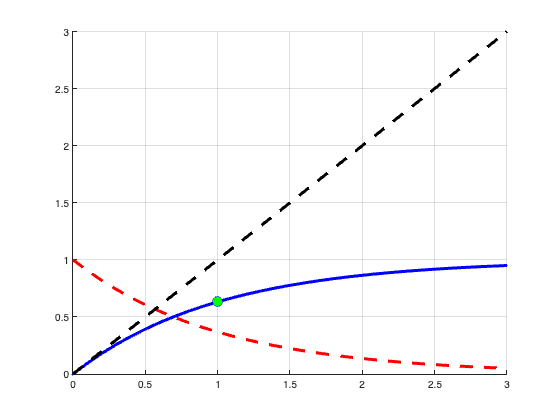


time=0:0.1:3;
hold on
grid on
plot(time, y(time), 'r--', "LineWidth",3);
plot(time, 1-y(time), 'b.-', "LineWidth",3)
plot(time, time, 'k--', "LineWidth",3)
plot(1, H(1), 'bo', "MarkerFaceColor", 'g', "MarkerSize",10)

## Questions 5-8

clc, clear, close all

% Question 5
syms y1(t) y2(t) f1(t) f2(t) F(s);
x = [y1; y2];
A= [-1, 0; 1, -1]; x0 = [1;1];
DE = diff(x,t) == A*x

$$DE(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}y_{1}\left(t\right)=-y_{1}\left(t\right)\\ \frac{\partial }{\partial t}y_{2}\left(t\right)=y_{1}\left(t\right)-y_{2}\left(t\right) \end{array}\right)$$


sol = dsolve(DE, x(0)==x0)

sol = struct with fields:
    y2: exp(-t) + t*exp(-t)
    y1: exp(-t)



% Question 6
f1 = int(sol.y1, 0, t)

$$f1 = 1-{\mathrm{e}}^{-t}$$

f2 = simplify(int(sol.y2, 0, t))

$$f2 = 2-{\mathrm{e}}^{-t}\,\left(t+1\right)-{\mathrm{e}}^{-t}$$


% Question 7
XL = inv((s*eye(2) - A))*x0

$$XL = \left(\begin{array}{c} \frac{1}{s+1}\\ \frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}} \end{array}\right)$$

xl = ilaplace(XL)

$$xl = \left(\begin{array}{c} {\mathrm{e}}^{-t}\\ {\mathrm{e}}^{-t}+t\,{\mathrm{e}}^{-t} \end{array}\right)$$


% Question 8
syms s
A=[-1 0; 1 -1] % system matrix

A =     -1     0
     1    -1


x0 = [1;1] % initial conditions

x0 =      1
     1


X =  inv((s*eye(2) - A))*x0 % find X here using inv()

$$X = \left(\begin{array}{c} \frac{1}{s+1}\\ \frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}} \end{array}\right)$$

F = X / s % find F here. Integration is division by s.

$$F = \left(\begin{array}{c} \frac{1}{s\,\left(s+1\right)}\\ \frac{\frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}}{s} \end{array}\right)$$

f = ilaplace(F) % find f here using ilaplace. 

$$f = \left(\begin{array}{c} 1-{\mathrm{e}}^{-t}\\ 2-t\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-t} \end{array}\right)$$

## Question 9

clc, clear, close all
syms s;

A = [-1, 0, 0, 0; 1, -1, 0, 0; 0, 1, -1, 0; 0, 0, 1, -1]

A =     -1     0     0     0
     1    -1     0     0
     0     1    -1     0
     0     0     1    -1


x0= [1;1;1;1]

x0 =      1
     1
     1
     1



X = inv(s*eye(4) - A) * x0

$$X = \left(\begin{array}{c} \frac{1}{s+1}\\ \frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}\\ \frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}+\frac{1}{{\left(s+1\right)}^{3}}\\ \frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}+\frac{1}{{\left(s+1\right)}^{3}}+\frac{1}{{\left(s+1\right)}^{4}} \end{array}\right)$$

F = X/s

$$F = \left(\begin{array}{c} \frac{1}{s\,\left(s+1\right)}\\ \frac{\frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}}{s}\\ \frac{\frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}+\frac{1}{{\left(s+1\right)}^{3}}}{s}\\ \frac{\frac{1}{s+1}+\frac{1}{{\left(s+1\right)}^{2}}+\frac{1}{{\left(s+1\right)}^{3}}+\frac{1}{{\left(s+1\right)}^{4}}}{s} \end{array}\right)$$

f = ilaplace(F) % Cumulative outflows in the time domain

$$f = \left(\begin{array}{c} 1-{\mathrm{e}}^{-t}\\ 2-t\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-t}\\ 3-2\,t\,{\mathrm{e}}^{-t}-\frac{t^{2}\,{\mathrm{e}}^{-t}}{2}-3\,{\mathrm{e}}^{-t}\\ 4-3\,t\,{\mathrm{e}}^{-t}-t^{2}\,{\mathrm{e}}^{-t}-\frac{t^{3}\,{\mathrm{e}}^{-t}}{6}-4\,{\mathrm{e}}^{-t} \end{array}\right)$$

f = matlabFunction(f) % convert f to a function

f = function_handle with value:
    @(t)[-exp(-t)+1.0;exp(-t).*-2.0-t.*exp(-t)+2.0;exp(-t).*-3.0-t.*exp(-t).*2.0-(t.^2.*exp(-t))./2.0+3.0;exp(-t).*-4.0-t.*exp(-t).*3.0-t.^2.*exp(-t)-(t.^3.*exp(-t))./6.0+4.0]


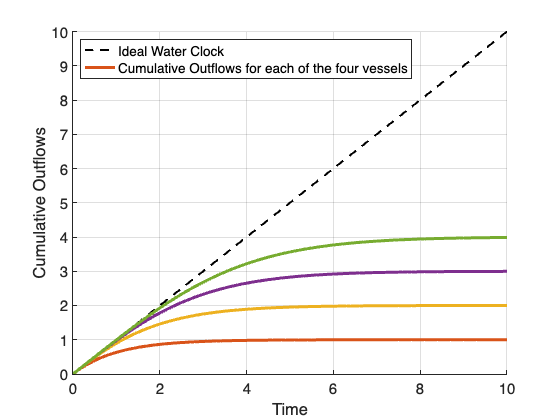


time = 0:0.1:10;
Y = f(time);

grid on
hold on
axis([0, 10, 0, 10])
set(gca, "FontSize", 15)
ideal = plot(time, time, 'k--', "LineWidth",2);
y1 = plot(time, Y(1,:), "LineWidth", 3);
y2 = plot(time, Y(2,:), "LineWidth", 3);
y3 = plot(time, Y(3,:), "LineWidth", 3);
y4 = plot(time, Y(4,:), "LineWidth", 3);
xlabel("Time")
ylabel("Cumulative Outflows")
legend([ideal, y1], ["Ideal Water Clock", "Cumulative Outflows for each of the four vessels"], "Location","NorthWest")


f_of_1 = f(1)

f_of_1 =     0.6321
    0.8964
    0.9767
    0.9957


## Question 10

clc, clear, close all

syms s;

N = 12 % Number of vessels, excluding the collection chamber

N = 12

subdiagonal = 1; diagonal = -1; superdiagonal = 0

superdiagonal = 0

A = full(gallery('tridiag', N, subdiagonal, diagonal, superdiagonal))

A =     -1     0     0     0     0     0     0     0     0     0     0     0
     1    -1     0     0     0     0     0     0     0     0     0     0
     0     1    -1     0     0     0     0     0     0     0     0     0
     0     0     1    -1     0     0     0     0     0     0     0     0
     0     0     0     1    -1     0     0     0     0     0     0     0
     0     0     0     0     1    -1     0     0     0     0     0     0
     0     0     0     0     0     1    -1     0     0     0     0     0
     0     0     0     0     0     0     1    -1     0     0     0     0
     0     0     0     0     0     0     0     1    -1     0     0     0
     0     0     0     0     0     0     0     0     1    -1     0     0


x0 = ones(N,1) % Initial conditions

x0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



X = inv(s*eye(N) - A) * x0

$$X = \begin{array}{l} \left(\begin{array}{c} \frac{1}{s+1}\\ \frac{1}{s+1}+\sigma_{1}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}+\sigma_{10}\\ \frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}+\sigma_{10}+\frac{1}{{\left(s+1\right)}^{12}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{{\left(s+1\right)}^{2}}\\ \sigma_{2}=\frac{1}{{\left(s+1\right)}^{3}}\\ \sigma_{3}=\frac{1}{{\left(s+1\right)}^{4}}\\ \sigma_{4}=\frac{1}{{\left(s+1\right)}^{5}}\\ \sigma_{5}=\frac{1}{{\left(s+1\right)}^{6}}\\ \sigma_{6}=\frac{1}{{\left(s+1\right)}^{7}}\\ \sigma_{7}=\frac{1}{{\left(s+1\right)}^{8}}\\ \sigma_{8}=\frac{1}{{\left(s+1\right)}^{9}}\\ \sigma_{9}=\frac{1}{{\left(s+1\right)}^{10}}\\ \sigma_{10}=\frac{1}{{\left(s+1\right)}^{11}} \end{array}$$

F = X/s

$$F = \begin{array}{l} \left(\begin{array}{c} \frac{1}{s\,\left(s+1\right)}\\ \frac{\frac{1}{s+1}+\sigma_{1}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}+\sigma_{10}}{s}\\ \frac{\frac{1}{s+1}+\sigma_{1}+\sigma_{2}+\sigma_{3}+\sigma_{4}+\sigma_{5}+\sigma_{6}+\sigma_{7}+\sigma_{8}+\sigma_{9}+\sigma_{10}+\frac{1}{{\left(s+1\right)}^{12}}}{s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{{\left(s+1\right)}^{2}}\\ \sigma_{2}=\frac{1}{{\left(s+1\right)}^{3}}\\ \sigma_{3}=\frac{1}{{\left(s+1\right)}^{4}}\\ \sigma_{4}=\frac{1}{{\left(s+1\right)}^{5}}\\ \sigma_{5}=\frac{1}{{\left(s+1\right)}^{6}}\\ \sigma_{6}=\frac{1}{{\left(s+1\right)}^{7}}\\ \sigma_{7}=\frac{1}{{\left(s+1\right)}^{8}}\\ \sigma_{8}=\frac{1}{{\left(s+1\right)}^{9}}\\ \sigma_{9}=\frac{1}{{\left(s+1\right)}^{10}}\\ \sigma_{10}=\frac{1}{{\left(s+1\right)}^{11}} \end{array}$$

f = ilaplace(F) % Cumulative outflows in the time domain

f = matlabFunction(f) % convert f to a function

f = function_handle with value:
    @(t)[-exp(-t)+1.0;exp(-t).*-2.0-t.*exp(-t)+2.0;exp(-t).*-3.0-t.*exp(-t).*2.0-(t.^2.*exp(-t))./2.0+3.0;exp(-t).*-4.0-t.*exp(-t).*3.0-t.^2.*exp(-t)-(t.^3.*exp(-t))./6.0+4.0;exp(-t).*-5.0-t.*exp(-t).*4.0-t.^2.*exp(-t).*(3.0./2.0)-(t.^3.*exp(-t))./3.0-(t.^4.*exp(-t))./2.4e+1+5.0;exp(-t).*-6.0-t.*exp(-t).*5.0-t.^2.*exp(-t).*2.0-(t.^3.*exp(-t))./2.0-(t.^4.*exp(-t))./1.2e+1-(t.^5.*exp(-t))./1.2e+2+6.0;exp(-t).*-7.0-t.*exp(-t).*6.0-t.^2.*exp(-t).*(5.0./2.0)-t.^3.*exp(-t).*(2.0./3.0)-(t.^4.*exp(-t))./8.0-(t.^5.*exp(-t))./6.0e+1-(t.^6.*exp(-t))./7.2e+2+7.0;exp(-t).*-8.0-t.*exp(-t).*7.0-t.^2.*exp(-t).*3.0-t.^3.*exp(-t).*(5.0./6.0)-(t.^4.*exp(-t))./6.0-(t.^5.*exp(-t))./4.0e+1-(t.^6.*exp(-t))./3.6e+2-(t.^7.*exp(-t))./5.04e+3+8.0;exp(-t).*-9.0-t.*exp(-t).*8.0-t.^2.*exp(-t).*(7.0./2.0)-t.^3.*exp(-t)-t.^4.*exp(-t).*(5.0./2.4e+1)-(t.^5.*exp(-t))./3.0e+1-(t.^6.*exp(-t))./2.4e+2-(t.^7.*exp(-t))./2.52e+3-(t.^8.*exp(-t))./4.032e+4+9.0;exp(-t).*-1.0e+1-t.*exp(-t).*9.0-t.^

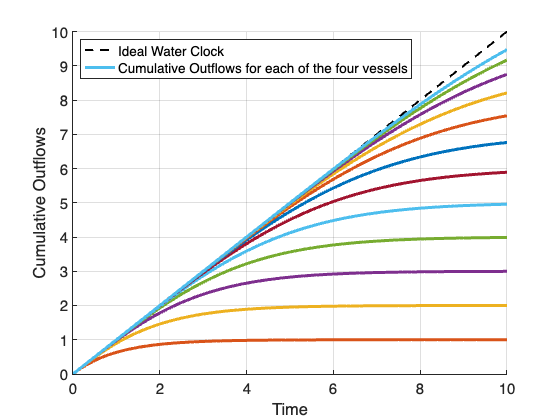


time = 0:0.1:10;
Y = f(time);

grid on
hold on
axis([0, 10, 0, 10])
set(gca, "FontSize", 15)
ideal = plot(time, time, 'k--', "LineWidth",2);
for i=1:12
    yh = plot(time, Y(i,:), "LineWidth", 3);
end
xlabel("Time")
ylabel("Cumulative Outflows")
legend([ideal, yh], ["Ideal Water Clock", "Cumulative Outflows for each of the four vessels"], "Location","NorthWest")


f_of_1 = f(1)

f_of_1 =     0.6321
    0.8964
    0.9767
    0.9957
    0.9993
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
